% Adding random covariates that are not meaningful may decrease power.
% It reduces the DF, but also can affect efficiency as the number of
% covariates grows relative to the number of observations in ways not strictly accounted for by DF.

% Including orthogonal covariates will not affect the regression slopes,
% but will affect the error variance.

n = 100;        % n observations
sigma = 5;      % noise sigma
k = 0;         % num of random nuisance covariates
niter = 1000;

tic
rng('shuffle')

% Create experimental effects of interest

x1 = [zeros(n/2, 1); ones(n/2, 1)];
x2 = [zeros(n/4, 1); ones(n/4, 1); zeros(n/4, 1); ones(n/4, 1)]; % orthogonal effect, with true b = 0, for false positives

% Iterate - random noise
[t_vals, p_vals, sig_vals, sig_falsepos_vals, b_vals, intercept_vals] = deal(zeros(niter, 1));

for i = 1:niter

    % true signal - with noise
    y = sigma .* randn(n, 1) + (1 * x1) + (0 * x2) + 10; % 10 = intercept (arbitrary value)

    K = randn(n, k);  % random covariates

    [b, dev, stat] = glmfit([x1 x2 K], y);  % intercept added first

    is_sig = stat.p(2) < 0.05 & stat.t(2) > 0; % effect of interest; consider sign errors too!!

    t_vals(i) = stat.t(2);
    p_vals(i) = stat.p(2);
    sig_vals(i) = is_sig;
    b_vals(i) = b(2);
    intercept_vals(i) = b(1);

    sig_falsepos_vals(i) = stat.p(3) < 0.05;

end
toc

% Summarize
pow_sim = sum(sig_vals) ./ niter

pow_sim = 0.1680

fpr_sim = sum(sig_falsepos_vals) ./ niter

fpr_sim = 0.0540

t_sim = mean(t_vals);
ste_b_sim = std(b_vals)  % standard error of beta across iterations

ste_b_sim = 1.0231

ste_i_sim = std(intercept_vals) % standard error of intercept

ste_i_sim = 0.8815

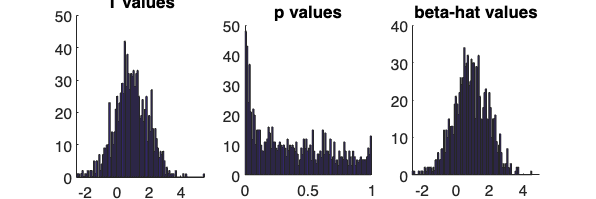


create_figure('summary', 1, 3);
hist(t_vals, 100)
title('T values');

subplot(1, 3, 2);
hist(p_vals, 100);
title('p values');

subplot(1, 3, 3);
hist(b_vals, 100);
title('beta-hat values');

## Now explore effects of number of random covariates

Put the whole sim, with iterations, in a sub-function

n_vals = [4*[14:3:80] 500 1000];             % must be divisible by 4 here in this sim
k_vals = [0 1 2 5 10 15 20 30 40 50];
niter = 5000;

[pow, fpr, t, ste_b, ste_i] = deal(zeros(length(n_vals), length(k_vals)));
tic

for n = 1:length(n_vals)

    for k = 1:length(k_vals)

        [pow(n, k), fpr(n, k), t(n, k), ste_b(n, k), ste_i(n, k)] = sim_power_fpr(n_vals(n), k_vals(k), sigma, niter);

        fprintf('.')
    end
    toc
    fprintf('|')
    
end

..........

|

..........

|

..........

|

..........

|

..........

|

..........

|

..........

|

..........

|

..........

|

..........

|

..........

|

..........

|

..........

|

..........

|

..........

|

..........

|

..........

|

..........

|

..........

|

..........

|

..........

|

..........

|

..........

|

..........

|

..........

|

fprintf('Done!\n')

Done!


k_names = cellstr(num2str(k_vals'))';

colors = seaborn_colors(length(k_vals));

create_figure('Power_FPR', 1, 2)

ans =   Figure (Power_FPR) with properties:

      Number: 7
        Name: 'Power_FPR'
       Color: [1 1 1]
    Position: [30 1050 1536 768]
       Units: 'pixels'

  Show all properties


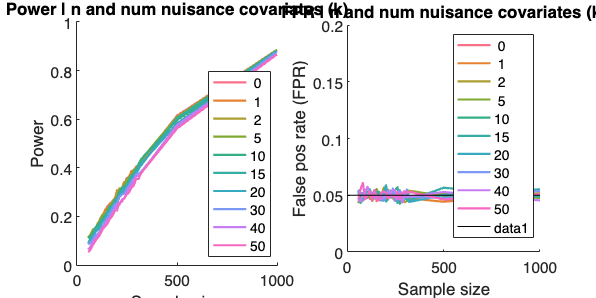

h = plot(n_vals, pow);
for i = 1:length(h), set(h(i), 'Color', colors{i}, 'LineWidth', 2); end
legend(k_names, 'Location', 'southeast')
xlabel('Sample size')
ylabel('Power')
title('Power | n and num nuisance covariates (k)')


subplot(1, 2, 2);
h = plot(n_vals, fpr);
for i = 1:length(h), set(h(i), 'Color', colors{i}, 'LineWidth', 2); end
legend(k_names)
xlabel('Sample size')
ylabel('False pos rate (FPR)')
title('FPR | n and num nuisance covariates (k)')
set(gca, 'YLim', [0 0.2]);
plot_horizontal_line(0.05);

create_figure('power_fpr2', 1, 2);
barplot_columns(pow, 'noviolins', 'dolines', 'names', k_names, 'colors', seaborn_colors(length(k_vals)), 'nofigure');

Col   1:  0	Col   2:  1	Col   3:  2	Col   4:  5	Col   5: 10	Col   6: 15	Col   7: 20	Col   8: 30	Col   9: 40	Col  10: 50	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
     Name     Mean_Value    Std_Error      T           P         Cohens_d
    ______    __________    _________    ______    __________    ________

    {' 0'}      0.3114      0.033333      9.342    1.8257e-09     1.8684 
    {' 1'}     0.31113      0.033275     9.3503    1.7953e-09     1.8701 
    {' 2'}     0.31001      0.033356     9.2939     2.014e-09     1.8588 
    {' 5'}      0.3074      0.033425     9.1968    2.4571e-09     1.8394 
    {'10'}     0.30236      0.033243     9.0956     3.027e-09     1.8191 
    {'15'}     0.29554      0

xlabel('Num nuisance covariates')
ylabel('Power')
title('Power | num nuisance covariates (k)')

subplot(1, 2, 2)
barplot_columns(fpr, 'noviolin', 'dolines', 'names', k_names, 'colors', seaborn_colors(length(k_vals)), 'nofigure');

Col   1:  0	Col   2:  1	Col   3:  2	Col   4:  5	Col   5: 10	Col   6: 15	Col   7: 20	Col   8: 30	Col   9: 40	Col  10: 50	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
     Name     Mean_Value    Std_Error       T           P         Cohens_d
    ______    __________    __________    ______    __________    ________

    {' 0'}     0.048456     0.00049092    98.704    2.2204e-15     19.741 
    {' 1'}     0.049592     0.00043197     114.8    2.2204e-15     22.961 
    {' 2'}     0.049312     0.00065585    75.188    2.2204e-15     15.038 
    {' 5'}     0.049664     0.00054378    91.331    2.2204e-15     18.266 
    {'10'}     0.051336     0.00057836    88.762    2.2204e-15     17.752 
    {'15'}      0.0502

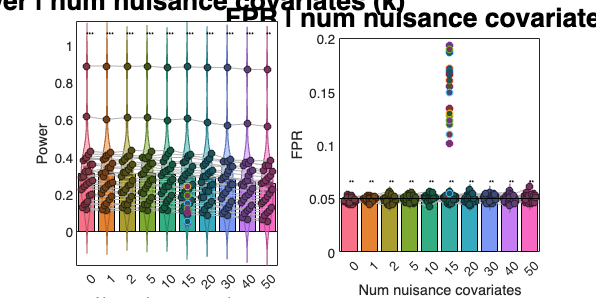

xlabel('Num nuisance covariates')
ylabel('FPR')
title('FPR | num nuisance covariates (k)')
set(gca, 'YLim', [0 0.2]);
plot_horizontal_line(0.05);

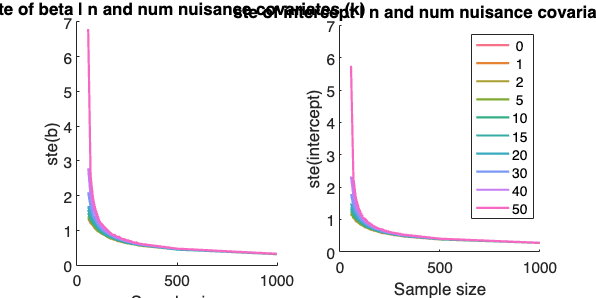

create_figure('Standard errors', 1, 2);
axh(1) = gca;
h = plot(n_vals, ste_b);
for i = 1:length(h), set(h(i), 'Color', colors{i}, 'LineWidth', 2); end
% legend(k_names, 'Location', 'northeast')
xlabel('Sample size')
ylabel('ste(b)')
title('ste of beta | n and num nuisance covariates (k)')

k_names = cellstr(num2str(k_vals'))';

subplot(1, 2, 2);
axh(2) = gca;
h = plot(n_vals, ste_i);
for i = 1:length(h), set(h(i), 'Color', colors{i}, 'LineWidth', 2); end
legend(k_names)
xlabel('Sample size')
ylabel('ste(intercept)')
title('ste of intercept | n and num nuisance covariates (k)')

equalize_axes(axh)

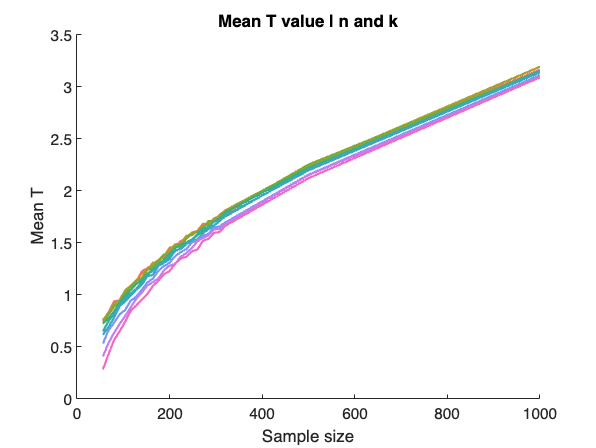

create_figure('Mean T values');
h = plot(n_vals, t);
for i = 1:length(h), set(h(i), 'Color', colors{i}, 'LineWidth', 2); end
% legend(k_names, 'Location', 'northeast')
xlabel('Sample size')
ylabel('Mean T')
title('Mean T value | n and k')


k_names = cellstr(num2str(k_vals'))';


create_figure('t given ratio of obs to predictors')

ans =   Figure (t given ratio of obs to predictors) with properties:

      Number: 23
        Name: 't given ratio of obs to predictors'
       Color: [1 1 1]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


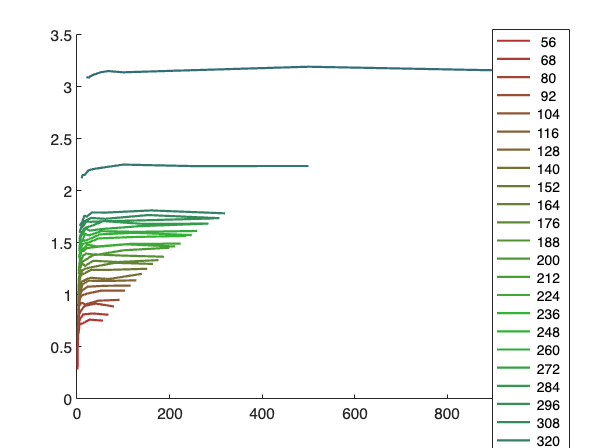


% num predictors is k + 3, intercept + two fixed effects + random nuisance

k_mat = repmat(k_vals, length(n_vals), 1);
n_mat = repmat(n_vals', 1, length(k_vals));
n_to_k = n_mat ./ k_mat;

h = plot(n_to_k', t');

[cm, n_colors] = colormap_tor([.7 .2 .2], [.2 .2 .7], [.2 .7 .2], 'n', 32);
n_colors = n_colors(1:length(n_vals));

n_names = cellstr(num2str(n_vals'))';

for i = 1:length(h), set(h(i), 'Color', n_colors{i}, 'LineWidth', 2); end
legend(h, n_names)


% theoretical power from t-values

df_mat = n_mat - (3 + k_mat);

expected_p = 2 * (1 - tcdf(t, df_mat));

tcrit = tinv(1 - (0.05 / 2), df_mat);

t_pow = nctcdf(tcrit, df_mat, t, 'upper'); % use noncentral T to get P of mean t > tcrit given df

create_figure('Estimated power from mean T')

ans =   Figure (Estimated power from mean T) with properties:

      Number: 25
        Name: 'Estimated power from mean T'
       Color: [1 1 1]
    Position: [30 1050 1536 768]
       Units: 'pixels'

  Show all properties


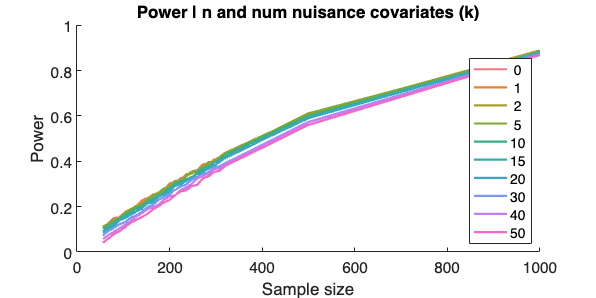

h = plot(n_vals, t_pow);
for i = 1:length(h), set(h(i), 'Color', colors{i}, 'LineWidth', 2); end
legend(k_names, 'Location', 'southeast')
xlabel('Sample size')
ylabel('Power')
title('Power | n and num nuisance covariates (k)')

function [pow, fpr, t, ste_b, ste_i] = sim_power_fpr(n, k, sigma, niter)

% Create experimental effects of interest

x1 = [zeros(n/2, 1); ones(n/2, 1)];
x2 = [zeros(n/4, 1); ones(n/4, 1); zeros(n/4, 1); ones(n/4, 1)]; % orthogonal effect, with true b = 0, for false positives

% Iterate - random noise
[t_vals, p_vals, sig_vals, sig_falsepos_vals, b_vals, intercept_vals] = deal(zeros(niter, 1));

rng('shuffle')

for i = 1:niter

    % true signal - with noise
    y = sigma .* randn(n, 1) + (1 * x1) + (0 * x2) + 10; % 10 = intercept (arbitrary value)

    K = randn(n, k);  % random covariates

    [b, dev, stat] = glmfit([x1 x2 K], y);  % intercept added first

    is_sig = stat.p(2) < 0.05 & stat.t(2) > 0; % effect of interest; consider sign errors too!!

    t_vals(i) = stat.t(2);
    p_vals(i) = stat.p(2);
    sig_vals(i) = is_sig;
    b_vals(i) = b(2);
    intercept_vals(i) = b(1);

    sig_falsepos_vals(i) = stat.p(3) < 0.05;

end

% Summarize
pow = sum(sig_vals) ./ niter;
fpr = sum(sig_falsepos_vals) ./ niter;
t = mean(t_vals);
ste_b = std(b_vals);  % standard error of beta across iterations
ste_i = std(intercept_vals); % standard error of intercept

end % subfunction